[y, Fs] = audioread("C:\Users\Rebecka\Documents\Liu\Kurser\Ljudteknik\TNM103-Ljudteknik\AnalogRytm_120BPM.wav")

y =     0.0016    0.0021
    0.0050    0.0066
    0.0029    0.0039
    0.0224    0.0291
    0.0646    0.0848
    0.0324    0.0435
   -0.0210   -0.0270
   -0.0572   -0.0750
   -0.0881   -0.1159
   -0.1141   -0.1502


Fs = 44100

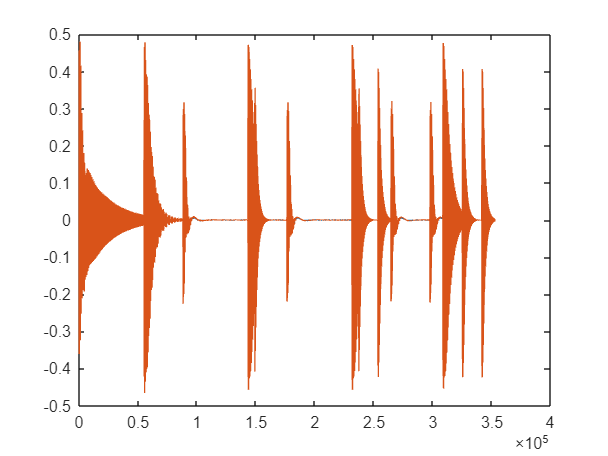

[z, FsEKO] = audioread("C:\Users\Rebecka\Documents\Liu\Kurser\Ljudteknik\TNM103-Ljudteknik\TimeFactor_RE501_120BPM.wav");
plot(y);

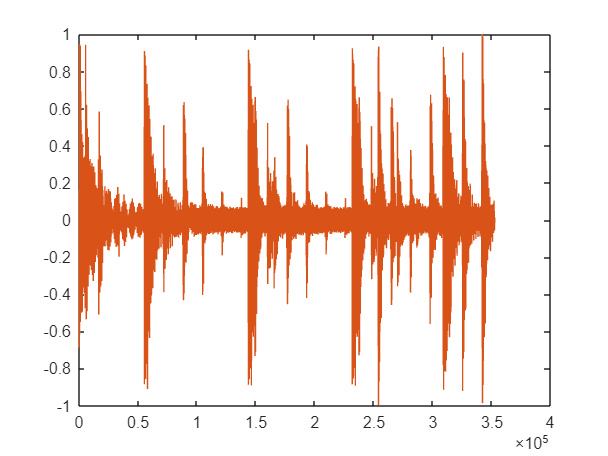

plot(z);

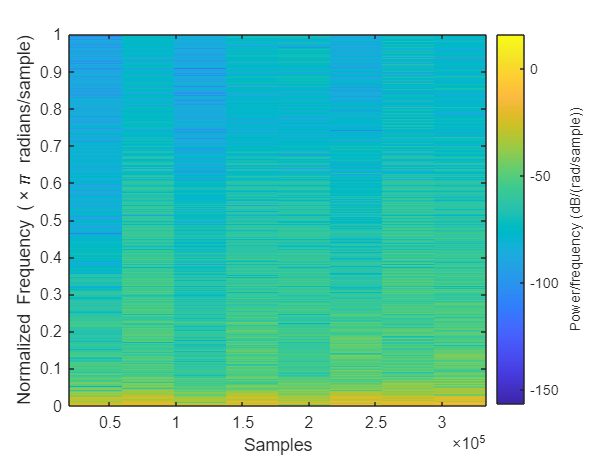

sound(z, FsEKO);
% Spektogram
%(spectrogram(y, window, noverlap, nfft))
(spectrogram(abs(y(:, 1)), 'yaxis'))

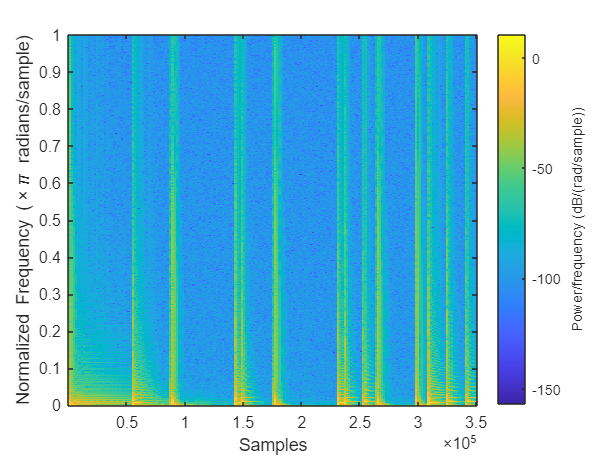

(spectrogram(abs(y(:, 1)), 2000, 200, 1000, 'yaxis'))

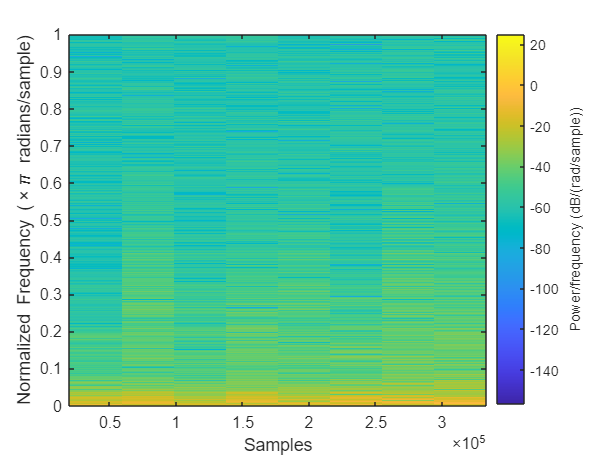

% Eko
(spectrogram(abs(z(:, 1)), 'yaxis'))

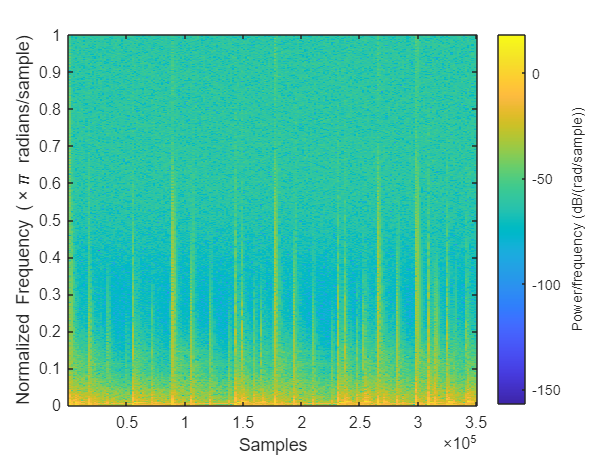

(spectrogram(abs(z(:, 1)), 2000, 200, 1000, 'yaxis'))

% Delay
[y, Fs] = audioread("C:\Users\Rebecka\Documents\Liu\Kurser\Ljudteknik\TNM103-Ljudteknik\AnalogRytm_120BPM.wav");

nollor = zeros(Fs/4, 1);
y1 = y(:, 1);

y1forlangd = [ y1 ; nollor ; nollor ; nollor ; nollor];
delay1 = [ nollor ; y1 ; nollor ; nollor ; nollor];
delay2 = [nollor ; nollor ; y1 ; nollor ; nollor];
delay3 = [nollor ; nollor ; nollor ; y1 ; nollor];
delay4 = [nollor ; nollor ; nollor ; nollor ; y1];


summa = (y1forlangd + delay1.*0.8 + delay2.*0.3 + delay3.*0.1 + delay4.*0.01);

%sound(summa, Fs)



% Reverb
numberOfAllpass = 3;
reverbTime = 500;
reverbGain = 0.8;
signalForReverb = summa;
mixLevel = 0.3;

for i = 0:numberOfAllpass-1
    noll = zeros(abs(reverbTime/100) * Fs, 1);
    reverbLength = ceil((reverbTime/1000) * Fs / (3.^i));
    signalForReverb = [signalForReverb;noll];
    signalForReverb = schroederAllpass(signalForReverb, reverbLength, reverbGain);
end
signalForReverbsize = size(signalForReverb);
signalsize = size(summa);
skillnad = signalForReverbsize - signalsize; 
skillnad1 = skillnad(1, 1);

signal1 = transpose(summa);
n = zeros(1, skillnad1);
k = signal1(1, :)

k =     0.0016    0.0050    0.0029    0.0224    0.0646    0.0324   -0.0210   -0.0572   -0.0881   -0.1141   -0.1401   -0.1673   -0.1874   -0.1993   -0.2099   -0.2192   -0.2287   -0.2345   -0.2397   -0.2426   -0.2458   -0.2494   -0.2551   -0.2584   -0.2620   -0.2662   -0.2643   -0.2507   -0.2331   -0.2134   -0.1937   -0.1732   -0.1533   -0.1326   -0.1215   -0.1197   -0.1210   -0.1230   -0.1266   -0.1345   -0.1434   -0.1528   -0.1632   -0.1735   -0.1821   -0.1912   -0.1990   -0.2062   -0.2146   -0.2227


signal2 = [signal1(1, :) n ; signal1(1, :) n];
signalny = transpose(signal2);
m = signalny(:, 1);

summaReverb = signalny(:, 1) + signalForReverb(:, 1);

lowsound = lowpass(summaReverb, 100, Fs); 
fianlsound = signalny(:, 1).*(1-mixLevel) + lowsound.*(0+mixLevel);

%sound(fianlsound, Fs)


[signal, Fs] = audioread("C:\Users\Rebecka\Documents\Liu\Kurser\Ljudteknik\TNM103-Ljudteknik\AnalogRytm_120BPM.wav")

signal =     0.0016    0.0021
    0.0050    0.0066
    0.0029    0.0039
    0.0224    0.0291
    0.0646    0.0848
    0.0324    0.0435
   -0.0210   -0.0270
   -0.0572   -0.0750
   -0.0881   -0.1159
   -0.1141   -0.1502


Fs = 44100


%sound(signal, Fs)
distLevel = 5;
distSound = (distLevel*signal)./(1+distLevel*abs(signal));
%sound(distSound, Fs)

% Förstärka och komp. förloppet
forstarkning = 2;
in = fianlsound;
out = zeros(length(in), 1);
out2 = out;

for i = 1:1:size(in)
    % Expansion
    out2(i) = in(i) * abs(in(i));
    % Kompression
    %out(i) = in(i)*(forstarkning-abs(in(i)));
end

for i = 1:1:size(in)
    % Kompression
  % out(i) = out2(i)*(forstarkning-abs(out2(i)));
   % Expansion
   %out2(i) = out(i) * abs(out(i));
end


m = length(out2);
noise = wgn(m, 1, 0).*0.03;
filternoise = highpass(noise, 6000, Fs).*0.05;
out2 = out2.*3 + filternoise;
rms(out)

ans = 0

rms(out2)

ans = 0.0892

rms(in)

ans = 0.0491


sound(out2, Fs)

%plot(out2)

